% compare_bgcSOLO_pressures.m
%
%--------------------------------------------------------------------------
% Script to start looking at comparison of 'target pressure' versus
% actual sampling pressure on various sensor axes of the BGC-SOLO.  The
% driving question is - how far off do each of the sensors sample from
% their target pressure, and is this negligible (or not) throughout the
% profile?
%
% Junk script started by T. Maurer 7/15/24 for Logan Grady to take over.
% :-)
%--------------------------------------------------------------------------

%Load the float directory as a table
SOLOdir = '\\seaecho.shore.mbari.org\floats\SIO\';
dirs = struct2table(dir(SOLOdir));

%Isolate float ID's
floatID = dirs.name(3:end-1);

sensor = 'CTD'

sensor = 'CTD'

fileType = 'phy'

fileType = 'phy'

     1



Unable to perform assignment because the size of the left side is 3-by-1 and the size of the right side is 5-by-1.

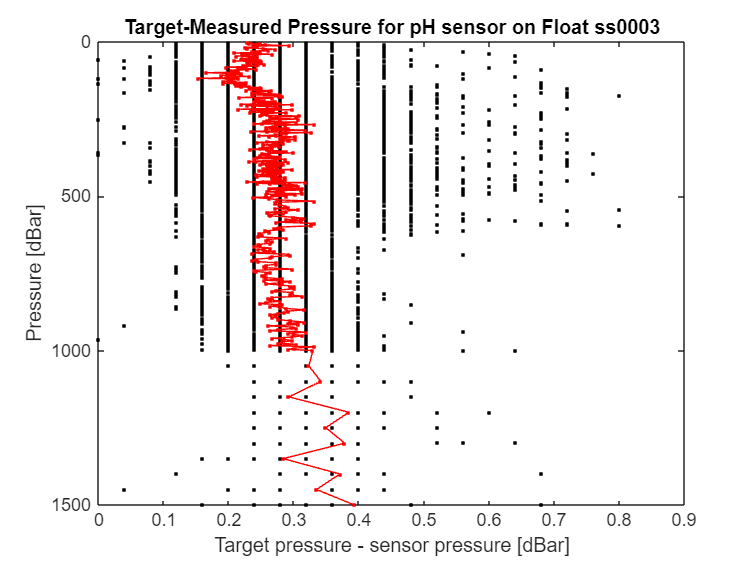

%i = 1
for i = 1:length(floatID)
    disp(i)
    floatDir = struct2table(dir([SOLOdir, floatID{i}]));
    if any(contains(floatDir.name, sensor))
        senDir = struct2table(dir([SOLOdir, floatID{i}, '\',sensor,'\*.',fileType]));
        folderName = senDir.folder{1};
        fileNames = senDir.name;
    
        %Retreive the first file to create an empty array with correct dimensions
        senCyc = fileNames{1};
        senFile = [folderName,'\',senCyc];
        
        %Read the text file and isolate the data
        fileText = readlines(senFile);
        dataLine = find(contains(fileText, "==")); %The line where the data begins
        if length(dataLine)==1
            data = split(fileText(dataLine+1:end-1,:));
        else
            data = split(fileText(dataLine(1)+1:dataLine(2)-1,:));
        end
        
        %Create a data structure with the TARGET PRESSURE as a separate array
        dSensor.targetPRES = str2double(data(:,2));
        
        %Create a data array to store all SENSOR PRESSURE
        dSensor.sensorPRES = nan(length(dSensor.targetPRES),length(fileNames));
        
        %Populate first column with data from the first file
        dSensor.sensorPRES(:,1) = str2double(data(:,5));
        for j = 2:length(fileNames)
        
            %Retreive the ith file to create an empty array with correct dimensions
            senCyc = fileNames{j};
            senFile = [folderName,'\',senCyc];
            
            %Read the text file and isolate the data
            fileText = readlines(senFile);
            dataLine = find(contains(fileText, "==")); %The line where the data begins
            if length(dataLine)==1
                data = split(fileText(dataLine(end)+1:end-1,:));
            else
                data = split(fileText(dataLine(1)+1:dataLine(2)-1,:));
            end
        
            %Populate ith column with data from the first file
            dSensor.sensorPRES(:,j) = str2double(data(:,5));
        end
        
        %Replace all -999 missing values with NaN
        badData = dSensor.sensorPRES==-999;
        dSensor.sensorPRES(badData) = NaN;
        
        %Calculate an array of differences from the target pressure
        dSensor.diffFromTarget = dSensor.targetPRES - dSensor.sensorPRES;
        dSensor.meanDiff = mean(dSensor.diffFromTarget, 2, "omitmissing");
        % %Format bins by every 100m
        % dAlk.binParams_sfc = 0:10:500;
        % dAlk.binParams_mid = 520:20:1000;
        % dAlk.binParams_deep = 1250:250:2001;
        % 
        % %Append all of them
        % dAlk.binParams = [dAlk.binParams_sfc dAlk.binParams_mid dAlk.binParams_deep];
        % 
        % %Create an empty array that's the same dimension as the pressure bins
        % dAlk.meanDiff = NaN(length(dAlk.binParams),1);
        % 
        % %Sort 2D pressure array by binned pressure
        % dAlk.bins = discretize(dAlk.sensorPRES,dAlk.binParams);
        % 
        % %Calculate the mean difference for every pressure bin
        % for k = 1:length(dAlk.binParams)
        %     dAlk.meanDiff(k) = mean(dAlk.diffFromTarget(dAlk.bins==k));
        % end
        
        newDir = "C:\Users\lgrady\Documents\MATLAB\ARGO_PROCESSING\MFILES\LG_WIP\SOLO_pressure_test\"+sensor;
        mkdir(newDir);

        plot(dSensor.diffFromTarget, dSensor.sensorPRES, '.k')
        hold on;
        plot(dSensor.meanDiff, dSensor.targetPRES, '.-r')
        set(gca, 'YDir','reverse')
        title("Target-Measured Pressure for "+sensor+" sensor on Float "+floatID{i});
        ylabel("Pressure [dBar]");
        xlabel("Target pressure - sensor pressure [dBar]")
        saveas(gcf,newDir+"\"+"presDif"+floatID{i}+"_"+sensor+".png")
        legend('Raw data','Mean by depth')
        close
    else
        disp('No ALK directory')
    end
end

%Calculating ascent rate
dtraj = ncload('1902666_Dtraj.nc')
whichMeas=find(dtraj.CYCLE_NUMBER==10 & dtraj.MEASUREMENT_CODE>=500 & dtraj.MEASUREMENT_CODE<=600);